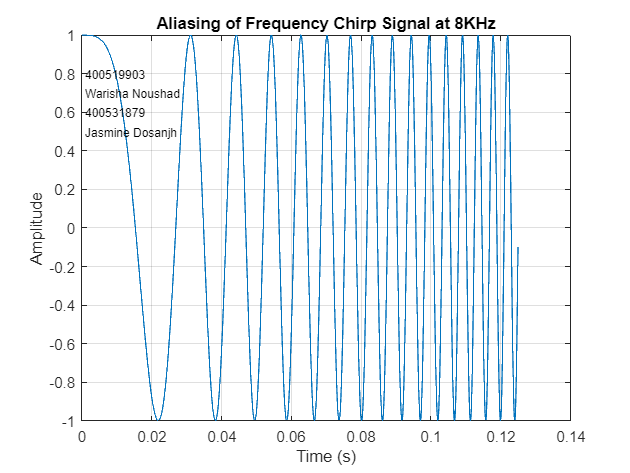

%% Question 5 (8KHz)
% Frequency for sin
f5 = 1; % New frequency for Question 5
mu = 2000;
%Sampling frequency
fs = 16000; %Sampling rate
Ts = 1/fs; %Sampling Period
%Plot the first 2000 samples
nplot = 2000;
t_short = (0:nplot-1)*Ts;
%Plot for 8 second signal
t = 8;
t_long = 0:Ts:t;
%Create the chirp signal c(t)
chirp = cos(pi*mu*(t_long.^2) + 2*pi*f5*t_long);
% Plot the 2000 samples 
figure;
plot(t_short, chirp(1:nplot));
title('Aliasing of Frequency Chirp Signal at 8KHz');
text(0.001,0.5, 'Jasmine Dosanjh', 'FontSize',8)
text(0.001,0.6, '400531879', 'FontSize',8)
text(0.001,0.7, 'Warisha Noushad', 'FontSize',8)
text(0.001,0.8, '400519903', 'FontSize',8)
xlabel('Time (s)');
ylabel('Amplitude');
grid on;
%Export graph
exportgraphics(gcf, "Q5(8KHz).jpg");

%Export audio
audiowrite('Lab3_Q5(8KHz)_soundwave.wav', chirp, fs);
